## Exercise 3: Interpolate Temperature in a Triangle Mesh

Once a global numbering for the nodes and for the elements is stablished, the usual way to describe the meshing  of a given region is through the matrices of the nodes, and the connectivity matrix where,

$\bullet$ The nodes' matrix's rows hold the coordinates of each global node. That is, the first row holds the coordinates of the first global node, the second row those of the second global node, and so on so forth. Thus,

                                                  
$$$$
\mathrm{nodes} = \left(\begin{array}{cc}
x_{1} & y_{1} \\
x_{2} & y_{2} \\
\vdots & \vdots \\
x_{N} & y_{N}\end{array}\right),$$
 

where $(x_{i}, y_{i})$ are the coordinates of the $i^{\mathrm{th}$- global node, $i = 1,2,\dots,N$; being $N$ the number of nodes.

$\bullet$ Each row of the  connectivity matrix contains the numbers of the first, second and third global nodes that make up each element of the mesh. The first row holds the numbers of the global nodes of the first element, the second row for the second, and so on. Hence,

                                            
$$$$
\mathrm{elem} = \left(\begin{array}{ccc}
nod_{1}^{1} & nod_{1}^{2} & nod_{1}^{3} \\
nod_{2}^{1} & nod_{2}^{2} & nod_{2}^{3} \\
\vdots & \vdots & \vdots \\
nod_{K}^{1} & nod_{K}^{2} & nod_{K}^{3} 
\end{array}\right).
$$$$


Here, the entries of the $j^{\mathrm{th}}$-row:  $nod_{j}^{1}$, $nod_{j}^{2}$, $nod_{j}^{3}$ give, respectively, the* global* numbers of the first, second and third* local *nodes of element $j$, for $j = 1,2,\dots,K$; being $K$ the number of elements.

See Exercise 2 for a concrete example.

Files required: `baryCoord.m, `plotElements`.m, and `meshHole.m. The latter two are packed in the files [additionalFiles.zip](https://numfactory.upc.edu/numfactory/subjects/FEM/Extra/additionalFiles.zip) and [meshFlesAll.rar](https://numfactory.upc.edu/numfactory/subjects/FEM/Extra/meshFilesAll.rar) respectively, that can be downloaded from Toni Susin's[ Numerical Factory.](https://numfactory.upc.edu/blog/2018/09/03/finite-element-introduction-course/)

clearvars
close all

## Geometry

Load the matrix of nodes and the connectivity from the file `meshHole.m`

p  = [0.83,0.7];
eval('meshHole'); %load nodes position and connectivity matrix 
                  %file meshHole.m
numNod = size(nodes,1); % number of nodes
numElem = size(elem,1); % number of elements

Assign the temperature at each node s.t. node $1$ is at  a temperature of $T(1) = 1^{\mathrm{o}}\mathrm{C}$, node  $2$ at a temperature of $T(2)=2^{\mathrm{o}}\mathrm{C}$,..., node `numNod `at a temperature of $T($`numNod`$)=$ `numNod`$^{\mathrm{o}}\mathrm{C}$. **Remark: **in a more realistic example, the temperature at each node will be, for instance, the given by the FEM. 

temp = 1:numNod; %Set the temperature at each node. Remark: this
                 %is just an example
temp = temp(:); %turn temp into a column vector

## Interpolation of the temperature

To find the interpolated temperature at point p, we proceed as in Exercise 2.

for e=1:numElem
    %vertexsElem=nodes(elem(e,:),:);
    n1=elem(e,1);
    n2=elem(e,2);
    n3=elem(e,3);
    v1=nodes(n1,:);
    v2=nodes(n2,:);
    v3=nodes(n3,:);
    vertexs=[v1;v2;v3];
    [alphas,isInside]=baryCoord(vertexs,p);
    if (isInside >= 1)
        nodsElem = [n1,n2,n3];
        vertexsElem = vertexs;
        interpTemp = alphas*temp(nodsElem); %Interpolate the temperature at point p using
                                             %the temperatures at the element's node
        fprintf('-----------------------------------------------------\n')
        fprintf('Fancy output, don''t try this at exams!!\n')                                     
        fprintf('-----------------------------------------------------\n')
        fprintf('Point: p=(%f, %f)\n',p)
        fprintf('Elem: %d\n',e) %Fancy output: don't try this at the exams!
        fprintf('Nodes: %d,%d,%d\n',nodsElem)
        fprintf('%20s\n','Vertexs Coords.')
        fprintf('%7s%11s\n','X','Y')
        fprintf('%12.5e%12.5e\n',vertexsElem')
        fprintf('Interpolated Temp.: T(%f,%f) = %.4f%cC',p,interpTemp,char(176))        
        fprintf('-----------------------------------------------------\n')
        % A faster vay to print out the results
        fprintf('A faster way to show the results...\n')
        format short e
        p
        e
        nodsElem
        vertexs
        interpTemp
        break;
    end
end

-----------------------------------------------------


Fancy output, don't try this at exams!!


-----------------------------------------------------


Point: p=(0.830000, 0.700000)


Elem: 189


Nodes: 109,112,92


     Vertexs Coords.


      X          Y


 8.74471e-01 6.21881e-01
 8.78502e-01 7.58024e-01
 7.39424e-01 7.49968e-01


Interpolated Temp.: T(0.830000,0.700000) = 104.0420°C

-----------------------------------------------------


A faster way to show the results...


p =    8.3000e-01   7.0000e-01


e =    189


nodsElem =    109   112    92


vertexs =    8.7447e-01   6.2188e-01
   8.7850e-01   7.5802e-01
   7.3942e-01   7.4997e-01


interpTemp =    1.0404e+02


## Plot

Draw the meshed area and mark the point $p$. We also mark the elemen's nodes

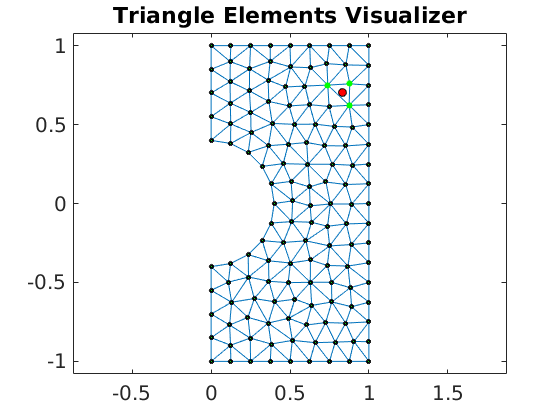

figure()
plotElementsOld(nodes,elem,0); %third argument is 0: labels not shown
axis equal
hold on
plot(p(1,1),p(1,2),'o','Marker','o','MarkerFaceColor','red',...
    'MarkerEdgeColor','black','MarkerSize',6)
plot(vertexsElem(:,1),vertexsElem(:,2),'og','Marker','o',...
    'MarkerFaceColor','green','MarkerSize',4)
hold off